# Medical Insurance Dataset Analysis

%% Medical Insurance Dataset Analysis
% Author: Paras Vikas Chavre
% Date: 11-Jul-24

## 1. Data Import and Cleaning

Explanation: The below steps import the datdata and ensure all variables are in the correct format for analysis. 

This sets up gives a clean dataset ready for exploratory data analysis and model training.

data = readtable('medical_insurance.xlsx');
format long g
data(1:5,:)

ans = 5×7 table
    age       sex         bmi      children    smoker        region          charges  
    ___    __________    ______    ________    _______    _____________    ___________

    19     {'female'}      27.9       0        {'yes'}    {'southwest'}      16884.924
    18     {'male'  }     33.77       1        {'no' }    {'southeast'}      1725.5523
    28     {'male'  }        33       3        {'no' }    {'southeast'}       4449.462
    33     {'male'  }    22.705       0        {'no' }    {'northwest'}    21984.47061
    32     {'male'  }     28.88       0        {'no' }    {'northwest'}      3866.8552


% Convert categorical and binary variables
data.sex = categorical(data.sex);
data.smoker = categorical(data.smoker);
data.region = categorical(data.region);

% Check for and remove rows with missing data
data = rmmissing(data);

##  2. Exploratory Data Analysis

Explanation : Computing basic statistics: mean, standard deviation, median for age, bmi, and charges. Computing these statistics helps us understand the central tendencies and variability of the key features in our dataset, providing insights into the general trends.

mean_age = mean(data.age);
std_age = std(data.age);
median_age = median(data.age);

mean_bmi = mean(data.bmi);
std_bmi = std(data.bmi);
median_bmi = median(data.bmi);

mean_charges = mean(data.charges);
std_charges = std(data.charges);
median_charges = median(data.charges);

fprintf('Statistics for Age:\n');

Statistics for Age:


fprintf('Mean Age: %.2f\n', mean_age);

Mean Age: 39.21


fprintf('Standard Deviation of Age: %.2f\n', std_age);

Standard Deviation of Age: 14.05


fprintf('Median Age: %.2f\n\n', median_age);

Median Age: 39.00




fprintf('Statistics for BMI:\n');

Statistics for BMI:


fprintf('Mean BMI: %.2f\n', mean_bmi);

Mean BMI: 30.66


fprintf('Standard Deviation of BMI: %.2f\n', std_bmi);

Standard Deviation of BMI: 6.10


fprintf('Median BMI: %.2f\n\n', median_bmi);

Median BMI: 30.40



fprintf('Statistics for Charges:\n');

Statistics for Charges:


fprintf('Mean Charges: %.2f\n', mean_charges);

Mean Charges: 13270.42


fprintf('Standard Deviation of Charges: %.2f\n', std_charges);

Standard Deviation of Charges: 12110.01


fprintf('Median Charges: %.2f\n', median_charges);

Median Charges: 9382.03


### Visualizing the relationship between age and charges using a scatter plot

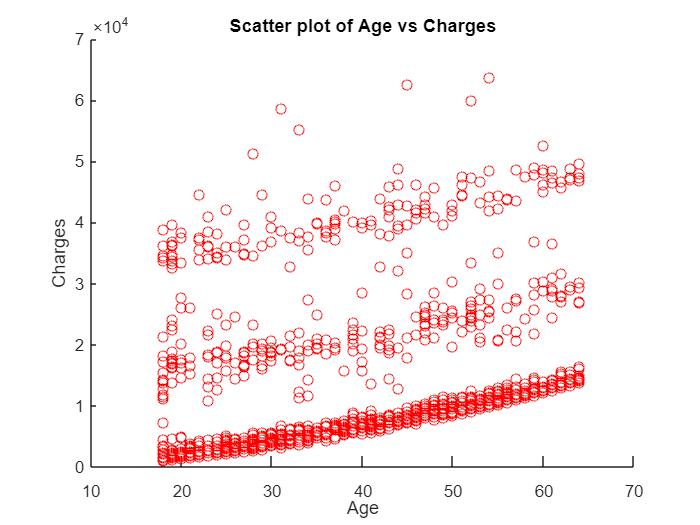

scatter(data.age, data.charges, 'red');
xlabel('Age');
ylabel('Charges');
title('Scatter plot of Age vs Charges');

### Visualizing the distribution of medical charges using a histogram

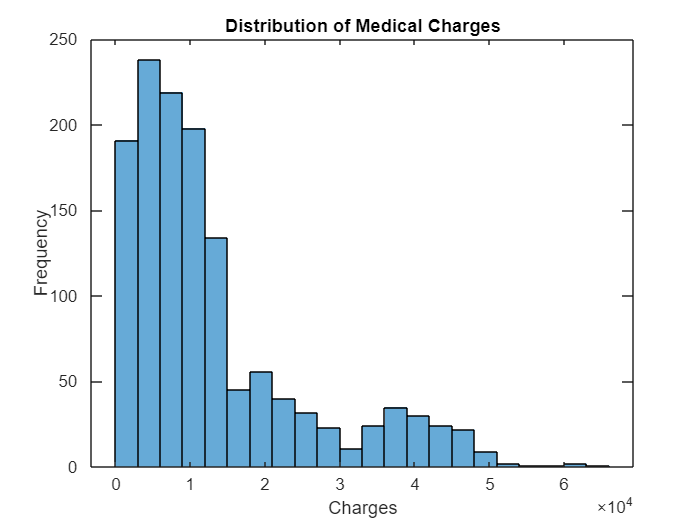

histogram(data.charges);
xlabel('Charges');
ylabel('Frequency');
title('Distribution of Medical Charges');

### Outlier Analysis

% Identifying outliers using the IQR method
Q1 = quantile(data.charges, 0.25);
Q3 = quantile(data.charges, 0.75);
IQR = Q3 - Q1;
lower_bound = Q1 - 1.5 * IQR;
upper_bound = Q3 + 1.5 * IQR;
outliers = data.charges > upper_bound;

% Count the number of outliers
num_outliers = sum(outliers);
fprintf('Number of outliers: %d\n', num_outliers);

Number of outliers: 139


% Characteristics of the outliers
outliers_data = data(outliers, :);
summary(outliers_data)

Variables:

    age: 139×1 double

        Values:

            Min          18   
            Median       43   
            Max          64   

    sex: 139×1 categorical

        Values:

            female       50   
            male         89   

    bmi: 139×1 double

        Values:

            Min        22.895 
            Median       35.2 
            Max         52.58 

    children: 139×1 double

        Values:

            Min          0    
            Median       1    
            Max          4    

    smoker: 139×1 categorical

        Values:

            no         3   
            yes      136   

    region: 139×1 categorical

        Values:

            northeast       28   
            northwest       20   
            southeast       57   
            southwest       34   

    charges: 139×1 double

        Values:

            Min     

% Table for specific statistics for outliers
outliers_summary = table(mean(outliers_data.age), std(outliers_data.age), median(outliers_data.age), ...
                         mean(outliers_data.bmi), std(outliers_data.bmi), median(outliers_data.bmi), ...
                         mean(outliers_data.charges), std(outliers_data.charges), median(outliers_data.charges), ...
                         'VariableNames', {'Mean_Age', 'STD_Age', 'Median_Age', 'Mean_BMI', 'STD_BMI', 'Median_BMI', 'Mean_Charges', 'STD_Charges', 'Median_Charges'});

disp('Summary Statistics for Outliers:');

Summary Statistics for Outliers:


disp(outliers_summary);

        Mean_Age            STD_Age         Median_Age        Mean_BMI            STD_BMI         Median_BMI      Mean_Charges        STD_Charges       Median_Charges
    ________________    ________________    __________    ________________    ________________    __________    ________________    ________________    ______________

    41.0791366906475    13.8014201895782        43        35.5646043165468    4.43491720364311       35.2       42103.9472058273    5582.16810707691      40974.1649  



### **Visualizing the distribution of charges by sex using a box chart.**

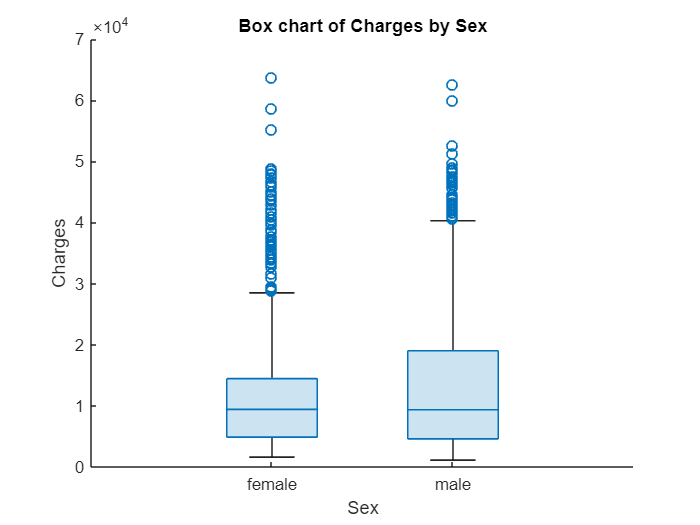

boxchart(data.sex, data.charges);
xlabel('Sex');
ylabel('Charges');
title('Box chart of Charges by Sex');

Males have higher medical charges compared to females. This could be due to a variety of factors such as differences in healthcare needs, lifestyle, or underlying health conditions between the sexes.

### Histogram of Age and BMI Distribution 

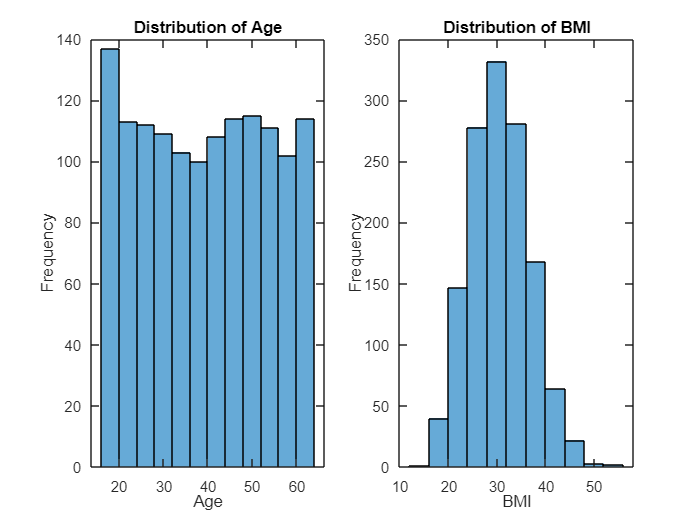

figure;

% Histogram for Age
subplot(1, 2, 1);
histogram(data.age, 'BinWidth', 4);
title('Distribution of Age');
xlabel('Age');
ylabel('Frequency');

% Histogram for BMI
subplot(1, 2, 2);
histogram(data.bmi, 'BinWidth', 4);
title('Distribution of BMI');
xlabel('BMI');
ylabel('Frequency');

### Creating a heatmap to show correlations between numerical variables

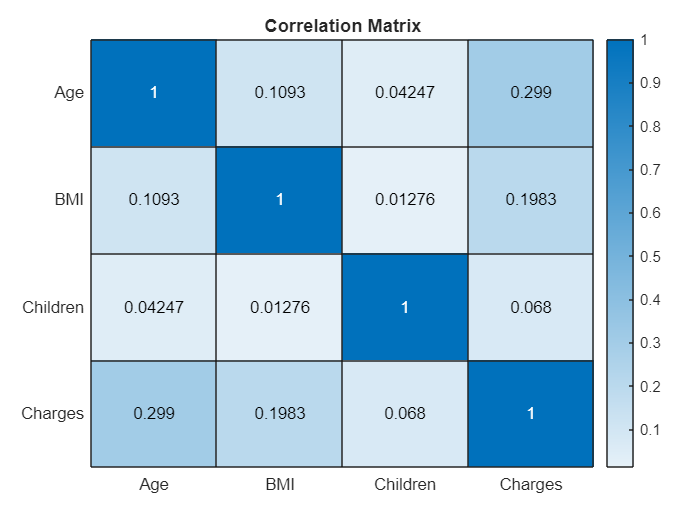

corr_matrix = corr(table2array(data(:, {'age', 'bmi', 'children','charges'})));
figure;
heatmap({'Age', 'BMI', 'Children', 'Charges'}, ...
        {'Age', 'BMI', 'Children', 'Charges'}, ...
        corr_matrix);
title('Correlation Matrix');

**Counting the Number of observations in each region, this would help us understand the distributions of the data across different regions, ensuring for regional variations in medical expenses.**

count_by_region = countcats(data.region);
region_names = categories(data.region);
for i = 1:length(region_names)
    fprintf('Region: %s, Count: %d\n', region_names{i}, count_by_region(i));
end

Region: northeast, Count: 324
Region: northwest, Count: 325
Region: southeast, Count: 364
Region: southwest, Count: 325


### Plot to compare smokers and non-smokers in terms of BMI and the medical charges they pay.

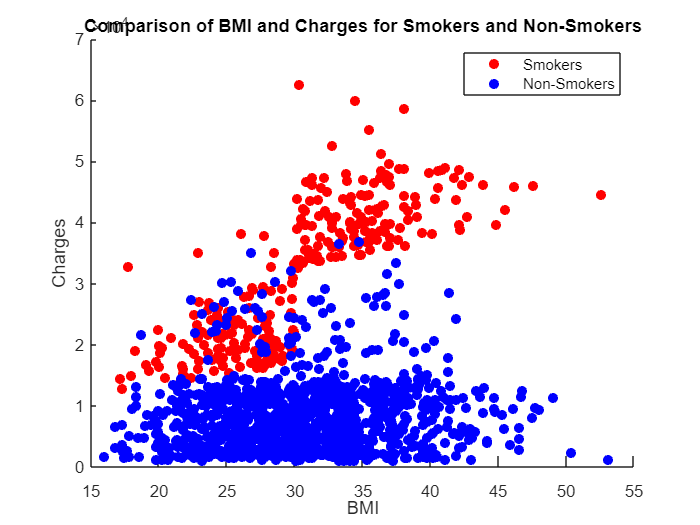

% Extract data for smokers and non-smokers
smoker_data = data(data.smoker == 'yes', :);
nonsmoker_data = data(data.smoker == 'no', :);

figure;
hold on;
scatter(smoker_data.bmi, smoker_data.charges, 'r', 'filled');
scatter(nonsmoker_data.bmi, nonsmoker_data.charges, 'b', 'filled');
xlabel('BMI');
ylabel('Charges');
title('Comparison of BMI and Charges for Smokers and Non-Smokers');
legend({'Smokers', 'Non-Smokers'});
% Display the plot
hold off;

- Smokers pay higher medical charges than non-smokers, especially as their BMI increases.

- Non-smokers generally have lower medical charges, and their charges do not increase as much with higher BMI.

- The plot highlights the financial impact of smoking on medical expenses.

## 3. Split the Dataset

% Setting the random seed for reproducibility
rng(42);

% Splitting the data into train (60%), validation (20%), and test (20%) sets
cv = cvpartition(height(data), 'HoldOut', 0.4);
trainData = data(training(cv), :);
tempData = data(test(cv), :);

cv_temp = cvpartition(height(tempData), 'HoldOut', 0.5);
valData = tempData(training(cv_temp), :);
testData = tempData(test(cv_temp), :);

## 4. Model Training and Evaluation

### Linear Regression using training data

mdl_linear = fitlm(trainData, 'charges ~ age + sex + bmi + children + smoker + region');
disp(mdl_linear);

Linear regression model:
    charges ~ 1 + age + sex + bmi + children + smoker + region

Estimated Coefficients:
                            Estimate                SE                 tStat                  pValue        
                        _________________    ________________    __________________    _____________________

    (Intercept)          -10925.493113712    1335.13592294322      -8.1830568153896     1.09708087265874e-15
    age                   249.98380951471    16.1750356052405      15.4549155634451     2.65010749887463e-47
    sex_male            -225.762129077987    449.983394146335    -0.501712134302826        0.616009111161702
    bmi                  317.314973685477    38.3639570146956      8.27117425775259     5.57146107792218e-16
    children        

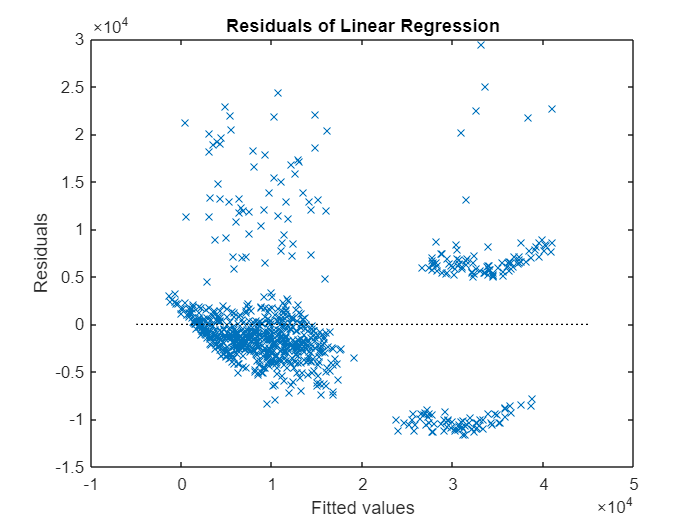

% Plot for residuals
figure;
plotResiduals(mdl_linear, 'fitted');
title('Residuals of Linear Regression');

#### Convert the Categorical Variable to Dummy Variable

% Convert categorical variables to dummy variables for training data
sex_dummy = dummyvar(trainData.sex);
smoker_dummy = dummyvar(trainData.smoker);
region_dummy = dummyvar(trainData.region);

% Create tables for the dummy variables
sex_dummy_table = array2table(sex_dummy, 'VariableNames', {'sex_female', 'sex_male'});
smoker_dummy_table = array2table(smoker_dummy, 'VariableNames', {'smoker_no', 'smoker_yes'});
region_dummy_table = array2table(region_dummy, 'VariableNames', ...
    {'region_northeast', 'region_northwest', 'region_southeast', 'region_southwest'});

% Concatenate dummy variables with the original table (excluding the original categorical columns and charges)
trainData_dummies = [trainData(:, {'age', 'bmi', 'children'}), ...
                     sex_dummy_table(:, 2:end), smoker_dummy_table(:, 2:end), region_dummy_table(:, 2:end)];

% Standardize the features
X_train = table2array(trainData_dummies);
X_train = (X_train - mean(X_train)) ./ std(X_train);
y_train = trainData.charges;

% Validation data
sex_dummy_val = dummyvar(valData.sex);
smoker_dummy_val = dummyvar(valData.smoker);
region_dummy_val = dummyvar(valData.region);

sex_dummy_table_val = array2table(sex_dummy_val, 'VariableNames', {'sex_female', 'sex_male'});
smoker_dummy_table_val = array2table(smoker_dummy_val, 'VariableNames', {'smoker_no', 'smoker_yes'});
region_dummy_table_val = array2table(region_dummy_val, 'VariableNames', ...
    {'region_northeast', 'region_northwest', 'region_southeast', 'region_southwest'});

valData_dummies = [valData(:, {'age', 'bmi', 'children'}), ...
                   sex_dummy_table_val(:, 2:end), smoker_dummy_table_val(:, 2:end), region_dummy_table_val(:, 2:end)];

X_val = table2array(valData_dummies);
X_val = (X_val - mean(X_val)) ./ std(X_val);
y_val = valData.charges;

% Test data
sex_dummy_test = dummyvar(testData.sex);
smoker_dummy_test = dummyvar(testData.smoker);
region_dummy_test = dummyvar(testData.region);

sex_dummy_table_test = array2table(sex_dummy_test, 'VariableNames', {'sex_female', 'sex_male'});
smoker_dummy_table_test = array2table(smoker_dummy_test, 'VariableNames', {'smoker_no', 'smoker_yes'});
region_dummy_table_test = array2table(region_dummy_test, 'VariableNames', ...
    {'region_northeast', 'region_northwest', 'region_southeast', 'region_southwest'});

testData_dummies = [testData(:, {'age', 'bmi', 'children'}), ...
                    sex_dummy_table_test(:, 2:end), smoker_dummy_table_test(:, 2:end), region_dummy_table_test(:, 2:end)];

X_test = table2array(testData_dummies);
X_test = (X_test - mean(X_test)) ./ std(X_test);
y_test = testData.charges;

% Ridge regression model with cross-validation to find the best lambda
mdl_ridge = fitrlinear(X_train, y_train, 'Learner', 'leastsquares', 'Regularization', 'ridge', 'Lambda', 'auto', 'CrossVal', 'on');
best_lambda_ridge = kfoldLoss(mdl_ridge, 'LossFun', 'mse', 'Mode', 'individual');
[~, best_idx_ridge] = min(best_lambda_ridge);
mdl_ridge = fitrlinear(X_train, y_train, 'Learner', 'leastsquares', 'Regularization', 'ridge', 'Lambda', mdl_ridge.Trained{best_idx_ridge}.Lambda);

% Lasso regression model with cross-validation to find the best lambda
[B_lasso, FitInfo_lasso] = lasso(X_train, y_train, 'CV', 10);
best_lambda_lasso = FitInfo_lasso.LambdaMinMSE;
mdl_lasso = fitrlinear(X_train, y_train, 'Learner', 'leastsquares', 'Lambda', best_lambda_lasso, 'Regularization', 'lasso');

% For Ridge Regression
ridge_coefficients = mdl_ridge.Beta;
feature_names = trainData_dummies.Properties.VariableNames;
[sorted_ridge_coef, ridge_idx] = sort(abs(ridge_coefficients), 'descend');
disp('Ridge Regression Feature Importance:');

Ridge Regression Feature Importance:


for i = 1:length(ridge_coefficients)
    fprintf('%s: %.4f\n', feature_names{ridge_idx(i)}, sorted_ridge_coef(i));
end

smoker_yes: 9748.8554
age: 3492.6008
bmi: 1928.2900
children: 605.5660
region_southwest: 460.9116
region_southeast: 318.1493
sex_male: 111.3550
region_northwest: 53.8705



% For Lasso Regression
lasso_coefficients = mdl_lasso.Beta;
[sorted_lasso_coef, lasso_idx] = sort(abs(lasso_coefficients), 'descend');
disp('Lasso Regression Feature Importance:');

Lasso Regression Feature Importance:


for i = 1:length(lasso_coefficients)
    if sorted_lasso_coef(i) ~= 0
        fprintf('%s: %.4f\n', feature_names{lasso_idx(i)}, sorted_lasso_coef(i));
    end
end

smoker_yes: 9688.1386
age: 3448.1226
bmi: 1842.3273
children: 539.8212
region_southwest: 327.2732
region_southeast: 174.7571
sex_male: 39.6609


% Count non-zero coefficients in Lasso
num_nonzero_lasso = sum(lasso_coefficients ~= 0);
disp(['Number of features kept by Lasso: ', num2str(num_nonzero_lasso)]);

Number of features kept by Lasso: 7


## 5. Model Evaluation

% Validate on validation data
predictions_ridge = predict(mdl_ridge, X_val);
predictions_lasso = predict(mdl_lasso, X_val);

% The mean squared error (MSE) for each model on the validation set
mse_ridge_val = mean((predictions_ridge - y_val).^2);
mse_lasso_val = mean((predictions_lasso - y_val).^2);

fprintf('Validation MSE (Ridge Regression): %f\n', mse_ridge_val);

Validation MSE (Ridge Regression): 31859324.487019


fprintf('Validation MSE (Lasso Regression): %f\n', mse_lasso_val);

Validation MSE (Lasso Regression): 32114250.075957


% Train on more models
% mdl_linear = fitlm(trainData, 'charges ~ age + sex + bmi + children + smoker + region');
mdl_tree = fitrtree(trainData, 'charges ~ age + sex + bmi + children + smoker + region');
mdl_rf = fitrensemble(trainData, 'charges ~ age + sex + bmi + children + smoker + region', 'Method', 'Bag');

% Feature Importance for Regression Tree
imp_tree = predictorImportance(mdl_tree);
[sorted_imp_tree, idx_tree] = sort(imp_tree, 'descend');
feature_names = mdl_tree.PredictorNames;

disp('Regression Tree Feature Importance:');

Regression Tree Feature Importance:


for i = 1:length(imp_tree)
    fprintf('%s: %.4f\n', feature_names{idx_tree(i)}, sorted_imp_tree(i));
end

smoker: 620174.6835
bmi: 175186.4985
age: 118933.8426
children: 16284.6808
region: 7776.7836
sex: 661.2048



% Feature Importance for Random Forest
imp_rf = predictorImportance(mdl_rf);
[sorted_imp_rf, idx_rf] = sort(imp_rf, 'descend');

disp('Random Forest Feature Importance:');

Random Forest Feature Importance:


for i = 1:length(imp_rf)
    fprintf('%s: %.4f\n', feature_names{idx_rf(i)}, sorted_imp_rf(i));
end

smoker: 897169.5183
bmi: 188614.4411
age: 164305.5870
children: 28815.7944
region: 28006.6032
sex: 9444.7879


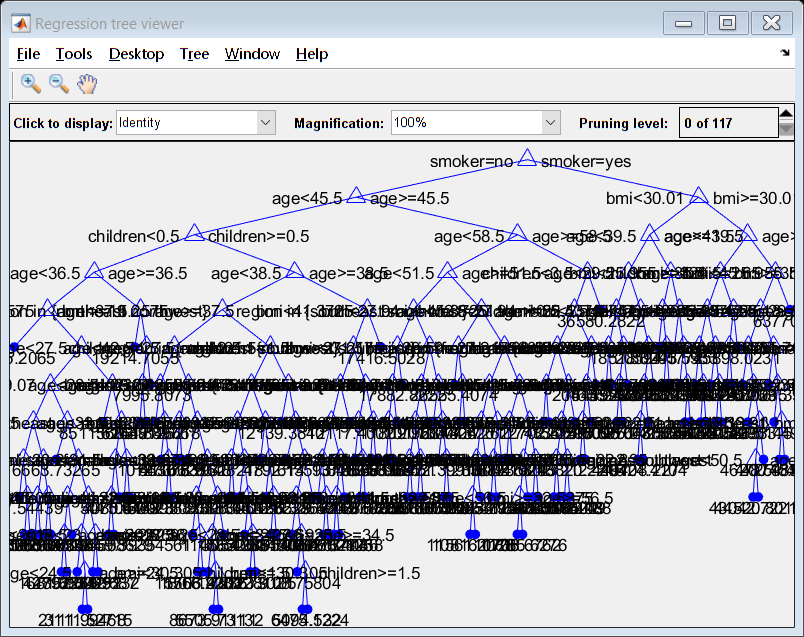


% Visualize the Regression Tree
view(mdl_tree, 'Mode', 'graph');


% Get number of nodes in the Regression Tree
num_nodes = size(mdl_tree.Children, 1) + 1;  % +1 for the root node
disp(['Number of nodes in the Regression Tree: ', num2str(num_nodes)]);

Number of nodes in the Regression Tree: 298



% Print some statistics about the tree
tree_stats = mdl_tree.ModelParameters;
disp(['Minimum leaf size: ', num2str(tree_stats.MinLeaf)]);

Minimum leaf size: 1


disp(['Minimum parent size: ', num2str(tree_stats.MinParent)]);

Minimum parent size: 10


disp(['Maximum number of splits: ', num2str(tree_stats.MaxSplits)]);

Maximum number of splits: 802


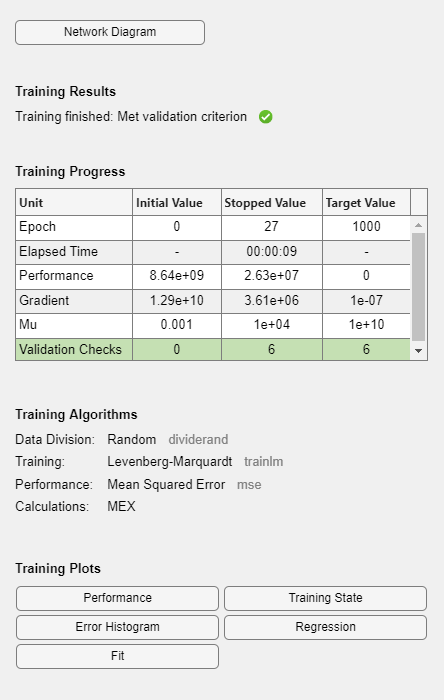

% For Neural Network, using the dummy variable data
inputs_nn = X_train';
targets_nn = y_train';

net = fitnet(10);
net = train(net, inputs_nn, targets_nn);


val_inputs_nn = X_val';

predictions_linear = predict(mdl_linear, valData);
predictions_tree = predict(mdl_tree, valData);
predictions_rf = predict(mdl_rf, valData);
predictions_nn = net(val_inputs_nn)';

mse_linear_val = mean((predictions_linear - valData.charges).^2);
mse_tree_val = mean((predictions_tree - valData.charges).^2);
mse_rf_val = mean((predictions_rf - valData.charges).^2);
mse_nn_val = mean((predictions_nn - valData.charges).^2);

fprintf('Validation MSE (Linear Regression): %f\n', mse_linear_val);

Validation MSE (Linear Regression): 31835298.317964


fprintf('Validation MSE (Regression Tree): %f\n', mse_tree_val);

Validation MSE (Regression Tree): 28990168.813444


fprintf('Validation MSE (Random Forest): %f\n', mse_rf_val);

Validation MSE (Random Forest): 20468414.901747


fprintf('Validation MSE (Neural Network): %f\n', mse_nn_val);

Validation MSE (Neural Network): 24264947.249327



% Selecting the best performing model based on validation MSE
[~, best_model_idx] = min([mse_linear_val, mse_ridge_val, mse_lasso_val, mse_tree_val, mse_rf_val, mse_nn_val]);
model_names = {'Linear Regression', 'Ridge Regression', 'Lasso Regression', 'Regression Tree', 'Random Forest', 'Neural Network'};
best_model_name = model_names{best_model_idx};

fprintf('Best performing model on validation set: %s\n', best_model_name);

Best performing model on validation set: Random Forest



% Evaluating the best model on the test data
test_inputs_nn = X_test';

switch best_model_name
    case 'Linear Regression'
        best_model_predictions = predict(mdl_linear, testData);
    case 'Ridge Regression'
        best_model_predictions = predict(mdl_ridge, X_test);
    case 'Lasso Regression'
        best_model_predictions = predict(mdl_lasso, X_test);
    case 'Regression Tree'
        best_model_predictions = predict(mdl_tree, testData);
    case 'Random Forest'
        best_model_predictions = predict(mdl_rf, testData);
    case 'Neural Network'
        best_model_predictions = net(test_inputs_nn)';
end

mse_test = mean((best_model_predictions - y_test).^2);

fprintf('Test set MSE for the best model (%s): %f\n', best_model_name, mse_test);

Test set MSE for the best model (Random Forest): 22201858.149962


% Print details of each model

% Linear Regression
disp('Linear Regression Model:');

Linear Regression Model:


disp(mdl_linear);

Linear regression model:
    charges ~ 1 + age + sex + bmi + children + smoker + region

Estimated Coefficients:
                            Estimate                SE                 tStat                  pValue        
                        _________________    ________________    __________________    _____________________

    (Intercept)          -10925.493113712    1335.13592294322      -8.1830568153896     1.09708087265874e-15
    age                   249.98380951471    16.1750356052405      15.4549155634451     2.65010749887463e-47
    sex_male            -225.762129077987    449.983394146335    -0.501712134302826        0.616009111161702
    bmi                  317.314973685477    38.3639570146956      8.27117425775259     5.57146107792218e-16
    children        


% Ridge Regression
disp('Ridge Regression Model Coefficients:');

Ridge Regression Model Coefficients:


disp(mdl_ridge.Beta);

          3492.60075896181
          1928.29003940118
          605.566039539718
         -111.355017712718
          9748.85544556273
         -53.8705366347938
         -318.149339568593
         -460.911602268854



% Lasso Regression
disp('Lasso Regression Model Coefficients:');

Lasso Regression Model Coefficients:


disp(mdl_lasso.Beta);

          3448.12261857904
           1842.3273478262
          539.821202511093
         -39.6609259425417
          9688.13856920248
                         0
         -174.757074953836
          -327.27321124414



% Regression Tree
disp('Regression Tree Model:');

Regression Tree Model:


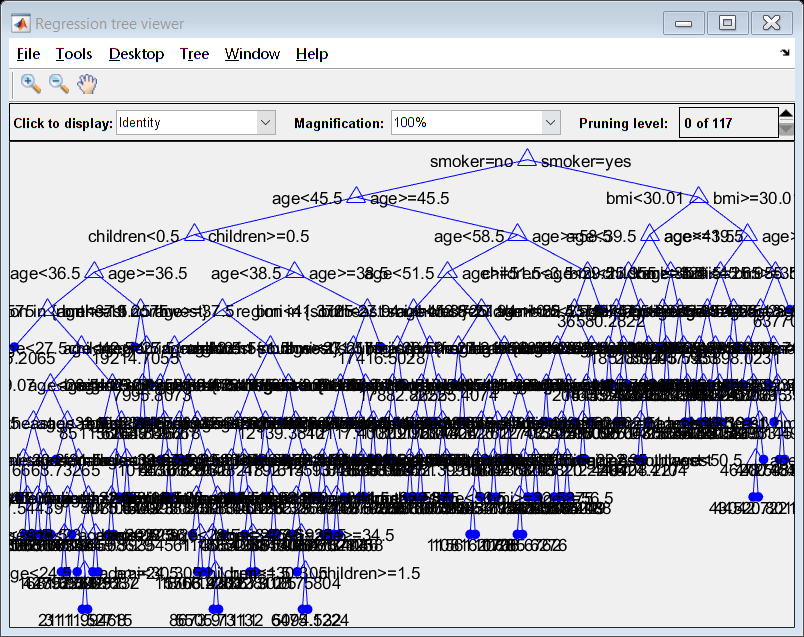

%view(mdl_tree, 'Mode', 'graph');

% Random Forest
disp('Random Forest Model:');

Random Forest Model:


disp(mdl_rf);

  RegressionBaggedEnsemble
           PredictorNames: {'age'  'sex'  'bmi'  'children'  'smoker'  'region'}
             ResponseName: 'charges'
    CategoricalPredictors: [2 5 6]
        ResponseTransform: 'none'
          NumObservations: 803
               NumTrained: 100
                   Method: 'Bag'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: []
       FitInfoDescription: 'None'
           Regularization: []
                FResample: 1
                  Replace: 1
         UseObsForLearner: [803×100 logical]


  Properties, Methods




% Neural Network
disp('Neural Network Model:');

Neural Network Model:


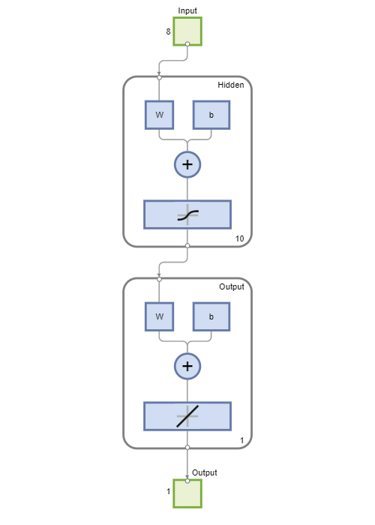

view(net);

## 6. Conclusion

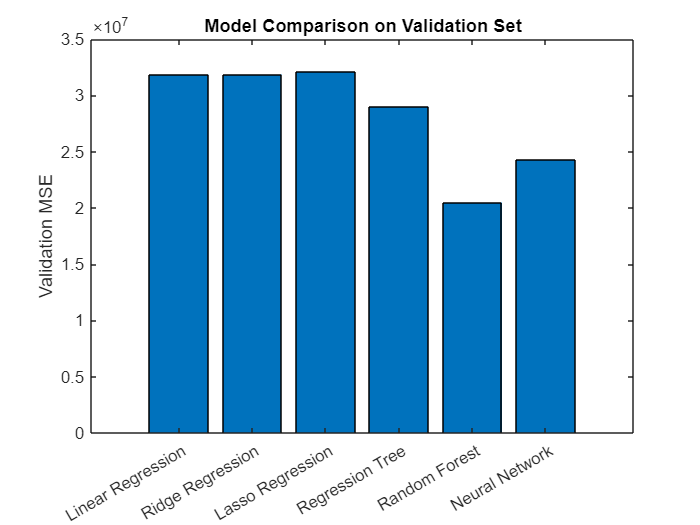

% Plotting the results
figure;
bar([mse_linear_val, mse_ridge_val, mse_lasso_val, mse_tree_val, mse_rf_val, mse_nn_val]);
set(gca, 'xticklabel', model_names);
ylabel('Validation MSE');
title('Model Comparison on Validation Set');

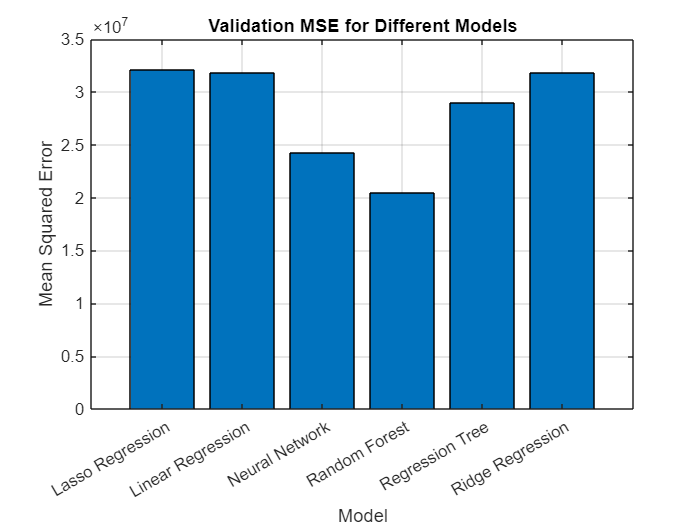

% Plotting the Validation MSE of each model
model_names = {'Linear Regression', 'Ridge Regression', 'Lasso Regression', 'Regression Tree', 'Random Forest', 'Neural Network'};
validation_mse = [mse_linear_val, mse_ridge_val, mse_lasso_val, mse_tree_val, mse_rf_val, mse_nn_val];

figure;
bar(categorical(model_names), validation_mse);
title('Validation MSE for Different Models');
ylabel('Mean Squared Error');
xlabel('Model');
grid on;

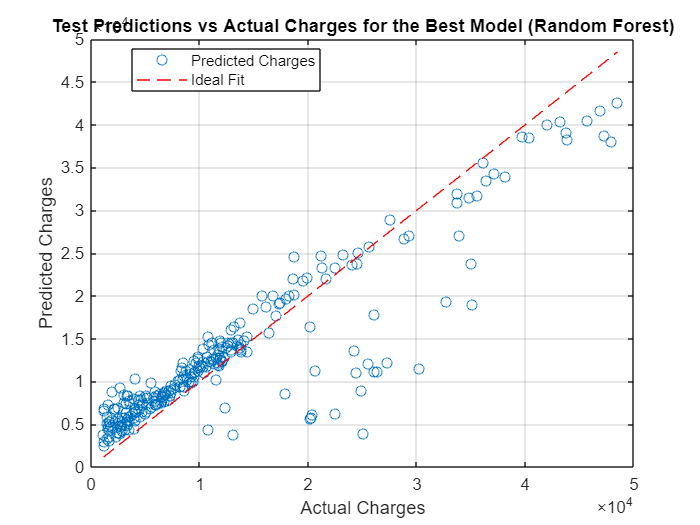


% Plotting the Test Predictions vs Actual Charges for the Best Model
figure;
plot(testData.charges, best_model_predictions, 'o');
hold on;
plot([min(testData.charges), max(testData.charges)], [min(testData.charges), max(testData.charges)], 'r--');
title(['Test Predictions vs Actual Charges for the Best Model (', best_model_name, ')']);
xlabel('Actual Charges');
ylabel('Predicted Charges');
legend('Predicted Charges', 'Ideal Fit', 'Location', 'Best');
grid on;